# DISEÑO FRECUENCIAL

CONTROLADOR EN ADELANTO 

%Hallar el valor de K

s=tf('s');
G=zpk(8/(s*(s+2)*(0.02*s+1)))%se evalua el limite de la FT


G =
 
       400
  --------------
  s (s+50) (s+2)
 
Continuous-time zero/pole/gain model.



%K=2,para tener una K de 20, se multiplica 2K=20, K=10
K1=dcgain(G)

K1 = Inf

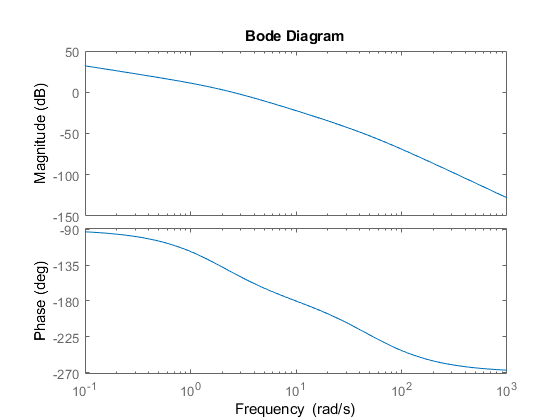

K=1;

G1=K*G;
bode(G1)

[mg,mf]=margin(G1)

mg = 13.0000

mf = 35.8306


%Calcular el MF 
%formula MF=MFd-mf+valor de ajuste

MF=180-45+7

MF = 142


%Calcular alfa

a=(1-sin(deg2rad(MF)))/(1+sin(deg2rad(MF)))

a = 0.2379


%Buscar en la grafica G(wm)

Gm=-20*log10(1/sqrt(a))

Gm = -6.2364

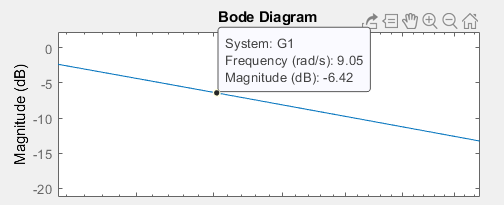

wm=1.36

wm = 1.3600


%Hallar valor de T

T=1/(wm*sqrt(a))

T = 1.5076

z=1/T

z = 0.6633

p=1/(a*T)

p = 2.7884

Kc=k/a

Kc = 84.0749

C=zpk(-z,-p,Kc)


C =
 
  84.075 (s+0.6633)
  -----------------
      (s+2.788)
 
Continuous-time zero/pole/gain model.




%Probar controlador, si cumple con especificaciones

L=C*G


L =
 
      33630 (s+0.6633)
  ------------------------
  s (s+2.788) (s+2) (s+50)
 
Continuous-time zero/pole/gain model.



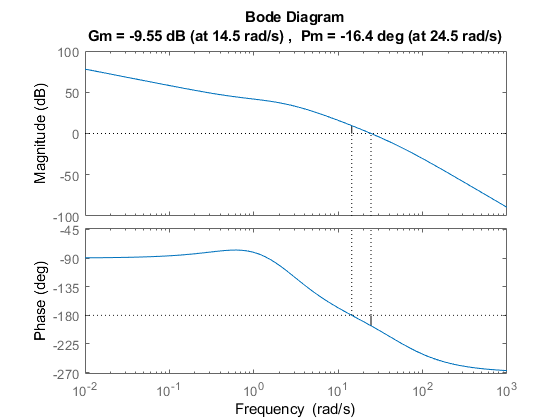

margin(L)

Cumplió con MF y Mg

%%Probar si cumple con Kv
Kv=dcgain(s*L)

Kv = 80.0000